# Week 9

## Matched Filters

Matched filters can be useful to determine whether a recieved signal is either the reflected signal with additive noise or just noise. This is useful in a radar system:

        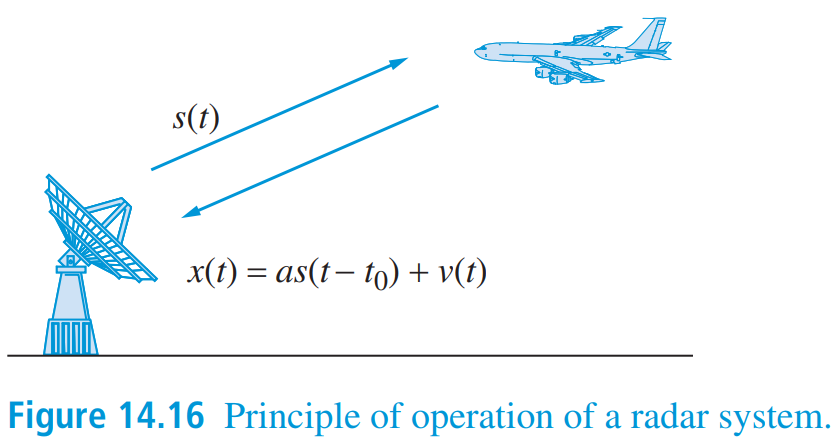

where

- $s\left(t\right)$ is a deterministic signal of known form

- $x\left(t\right)$ is the signal measured by the radar if an object is present

-   $a$ is an attenuation factor  

-   $t_0$ is the round-trip delay

-   $v\left(t\right)$ is random noise

The measured signal by the radar can be two things:

- If an object happens to be in the way then part of the signal is reflected plus noise

- If there is no object in the way of the transmitted pulse, the received signal is just noise

To help us determine whether an object is present, we pass the received signal into a $p-1$-tap FIR filter:

         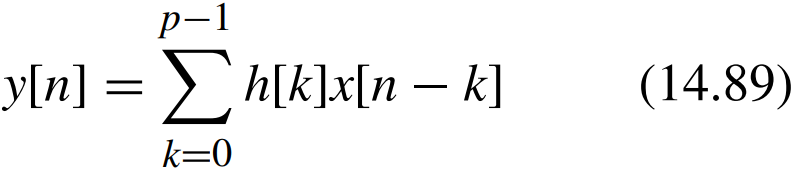

This 

         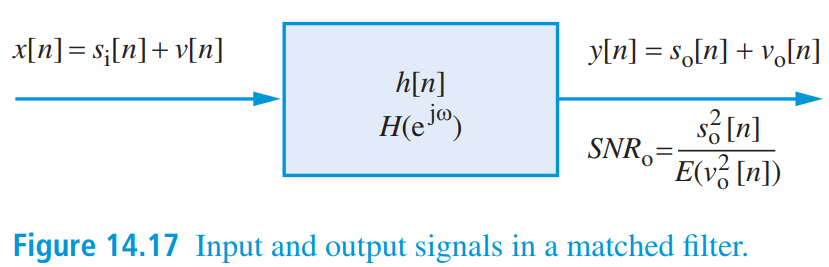

Our objective is to find the impulse $h\left\lbrack n\right\rbrack$ so that the output signal-to-noise ratio ${\mathrm{SNR}}_o$ is maximised:

        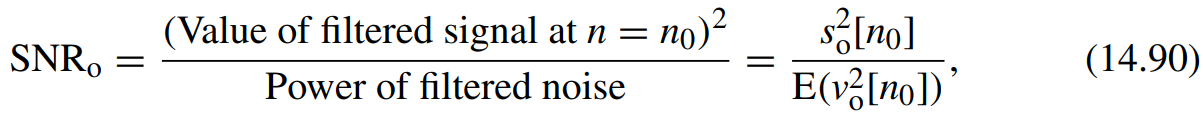

The solution is known as a *matched filter. *The impulse response of the optimum filter is

        

where 

        ${\mathit{\mathbf{R}}}_v$ is the autocorrelation matrix of the zero-mean wide-sense stationary noise $v\left\lbrack n\right\rbrack$

        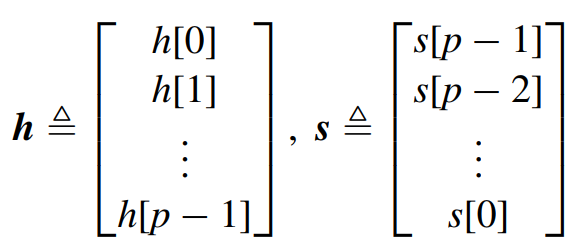

        $\kappa$ is a normalisation factor

Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        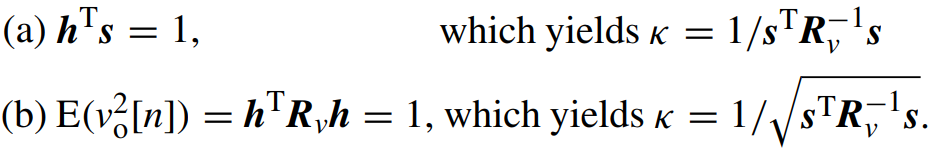

The maximum possible value of the output SNR is given by:

        

In summary, to design af matched filter we need two information:

- the autocorrelation sequence of the noise $r_{\mathrm{vv}} \left\lbrack \ell \right\rbrack$

- the transmitted signal $s\left\lbrack n\right\rbrack$

### White noise process

If the noise if white 

The autocorrelatiom matrix of white noise is ${\mathit{\mathbf{R}}}_v =\sigma_v^2 \mathit{\mathbf{I}}$. Then equations (14.97) and (14.98) are simplified to: